l = 5;
p = 7;
n = 10;
m = 12;
num_corrupt = 1; % number of corruptions 
size_corrupt= 100; % size of corruptions 
num_its = 1000; % number of iterations

%generate tensors
A = randn(m,l,n);
X_true = randn(l,p,n);
B = tprod(A,X_true);

dims = prod(size(B));
ix_lin = randsample(dims,num_corrupt);

[ix_sub1, ix_sub2, ix_sub3] = ind2sub(size(B),ix_lin);
for i=1:num_corrupt
    B(ix_sub1(i),ix_sub2(i),ix_sub3(i)) = B(ix_sub1(i),ix_sub2(i),ix_sub3(i)) + size_corrupt; %original
end 

%TRK
[~,its] = tRK(A,B,randn(l,p,n),num_its);

%record errors for TRK
errs = [];
for j = 1:num_its+1
    est = its{j} - X_true;
    errs = [errs,norm(est(:))];
end

%QTRK
qv = 0.9 %quantile value

qv = 0.9000

[~,its] = qRK(A,B,randn(l,p,n),num_its, qv);

Iteration: 18 -- Skipping slice 11, q = 0.91667
Iteration: 24 -- Skipping slice 11, q = 0.91667
Iteration: 30 -- Skipping slice 11, q = 0.91667
Iteration: 34 -- Skipping slice 11, q = 0.91667
Iteration: 35 -- Skipping slice 11, q = 0.91667
Iteration: 43 -- Skipping slice 11, q = 0.91667
Iteration: 68 -- Skipping slice 11, q = 0.91667
Iteration: 80 -- Skipping slice 11, q = 0.91667
Iteration: 102 -- Skipping slice 11, q = 0.91667
Iteration: 114 -- Skipping slice 11, q = 0.91667
Iteration: 115 -- Skipping slice 11, q = 0.91667
Iteration: 117 -- Skipping slice 11, q = 0.91667
Iteration: 119 -- Skipping slice 11, q = 0.91667
Iteration: 131 -- Skipping slice 11, q = 0.91667
Iteration: 134 -- Skipping slice 11, q = 0.91667
Iteration: 142 -- Skipping slice 11, q = 0.91667
Iteration: 152 -- Skipping slice 11, q = 0.91667
Iteration: 158 -- Skipping slice 11, q = 0.91667
Iteration: 171 -- Skipping slice 11, q = 0.91667
Iteration: 174 -- Skipping slice 11, q = 0.91667
Iteration: 185 -- Skipping s


%record errors for QTRK
errs2 = [];
for j = 1:num_its+1
    est = its{j} - X_true;
    errs2 = [errs2,norm(est(:))];
end

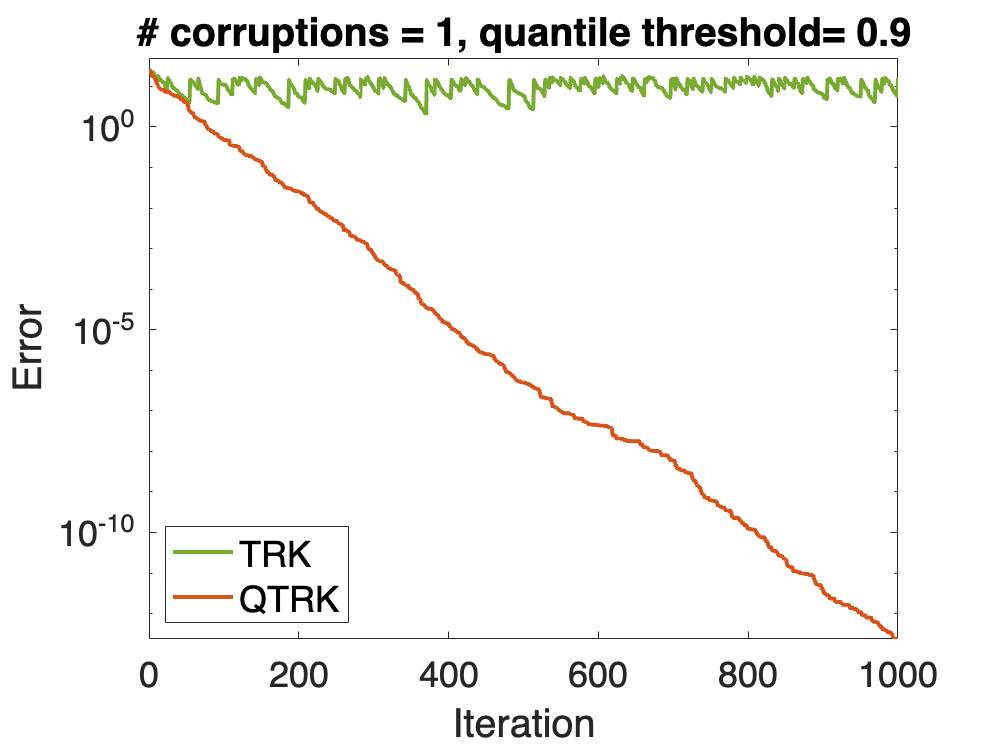

%comparison
semilogy(errs,'Linewidth',2, 'Color', "#77AC30")
title("# corruptions = " + num_corrupt + ', quantile threshold= ' + qv)

xlabel ('Iteration', FontSize=18)
ylabel('Error', FontSize=18)
axis([0 num_its 0 50])
set(gca, 'FontSize', 18)
hold on

semilogy(errs2,'Linewidth',2, 'Color', "#D95319")

hold off

legend('TRK','QTRK', Location='southwest', FontSize = 18);